clear all
close all

data = readmatrix("Primary_Data.csv");
sim = readmatrix("20wind_openrocket.csv");
regression = readmatrix("Full_Scale_Flight_Regression.txt");
simupdate = readmatrix("20wind_openrocket-update.csv");
%simupdatenew = readmatrix("Scale_Updated_Analysis_Different_Motor.csv");

plot(sim(:,1),sim(:,2),'color','black')
hold on
plot(data(:,1),data(:,2),'color','r')
plot(regression(:,1),regression(:,3),'color','g')
plot(simupdate(:,1),simupdate(:,2),'color','magenta')
% plot(simupdatenew(:,1),simupdatenew(:,2))


% l = length(sim(:,1));
% x = 1:l;
% main = ones(l,1)*600;
% plot(x,main)

xlabel('Time (s)')
ylabel('Altitude (ft)') 

% title('Scale Flight Data',"FontSize",14)

title('Flight Profile (CD Update)','FontSize',14)
legend('Openrocket Simulation','Stratologger SL100','Flight Regression','OpenRocket Update')
% legend('OpenRocket Simulation','Flight Data','Flight Regression','OpenRocket Update (Parachutes)',...
%     'Openrocket Update (New Motor/Parachutes)','Main Ejection')
hold off
% xlim([0.0 50.0])
ylim([-100 5000])


Set Figure Size

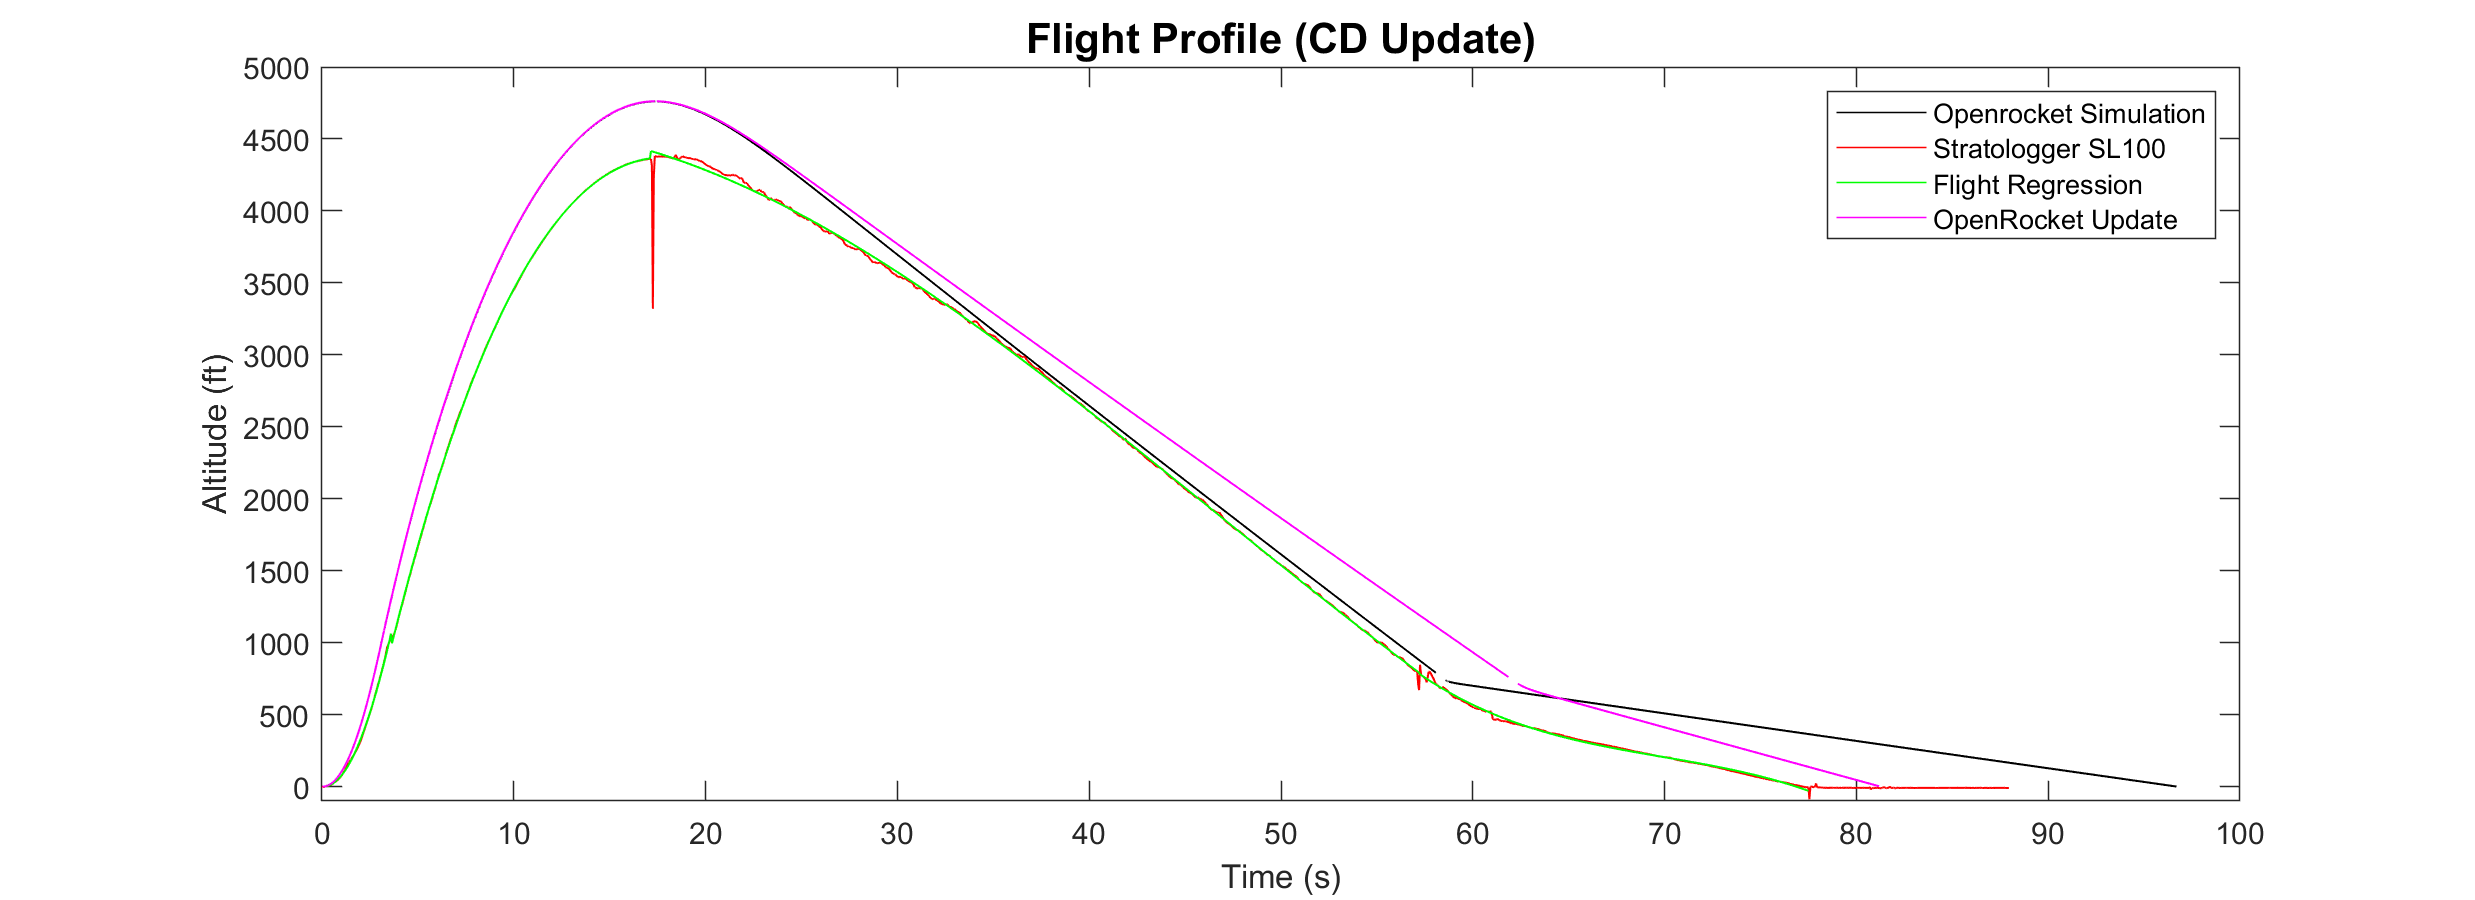

x0=10;
y0=10;
width=1100;
height=400;
set(gcf,'position',[x0,y0,width,height])